## Clear commands

clc
clear


## Load, recentre and symmetrise data

newsection("Load, recentre and symmetrise data");

---------------------------------------------------------------------------
Load, recentre and symmetrise data
---------------------------------------------------------------------------


Load data

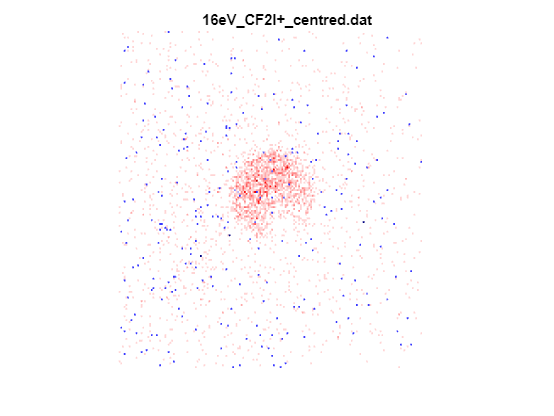

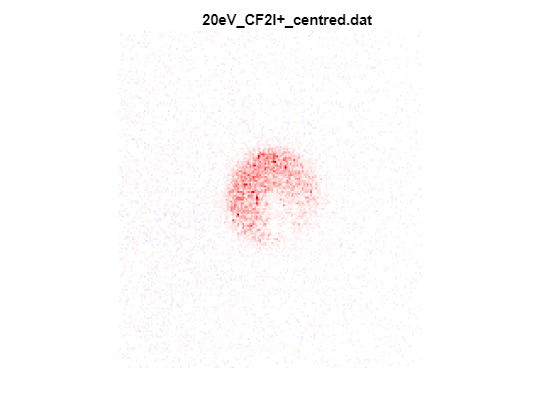

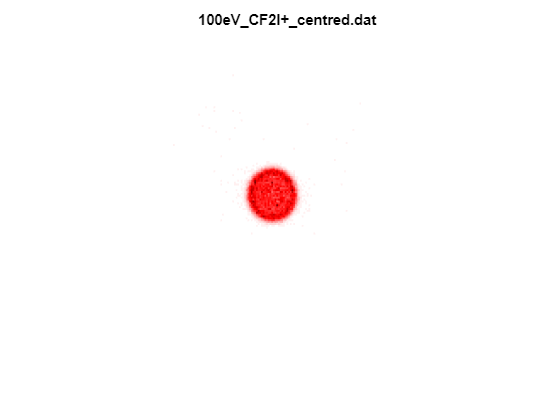

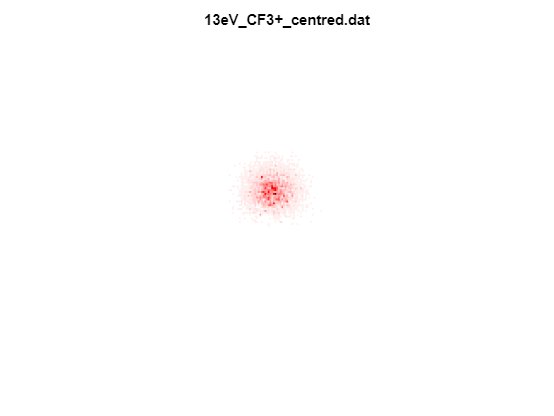

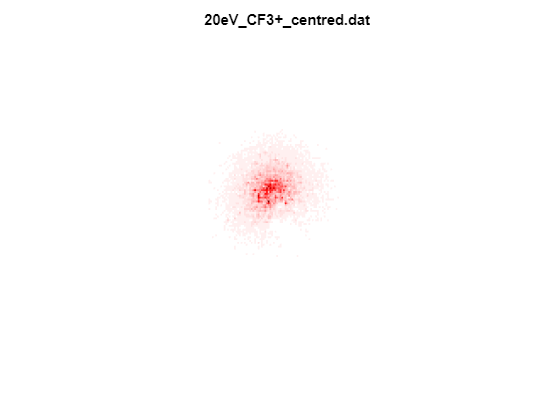

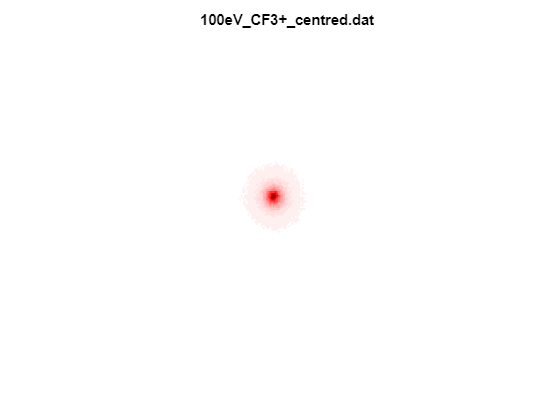

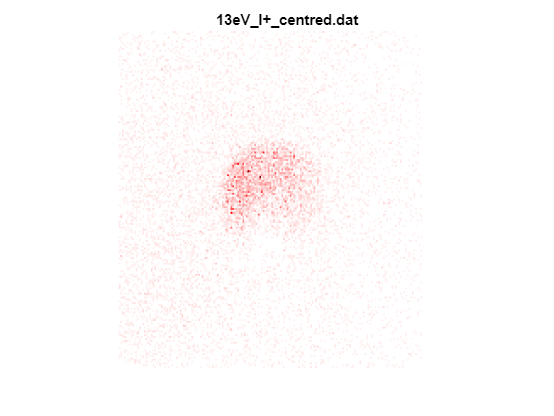

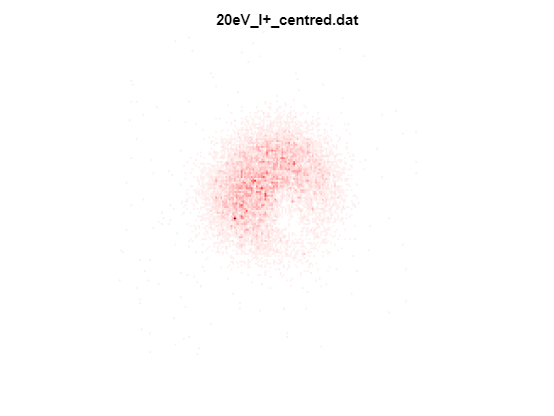

filename = ["16eV_CF2I+_centred.dat", "20eV_CF2I+_centred.dat", "100eV_CF2I+_centred.dat", "13eV_CF3+_centred.dat", "20eV_CF3+_centred.dat", "100eV_CF3+_centred.dat", "13eV_I+_centred.dat", "20eV_I+_centred.dat", "100eV_I+_centred.dat"];

for i = 1:length(filename)
    image(:, :, i) = table2array(readtable("C:\Users\nlhdr\OneDrive - Heriot-Watt University\PhD\Projects\Denoising for Oxford\Centred Data from Alex (10.01.24)\" + filename(i) + ""));
    image_cropped(:, :, i) = imcrop(image(:, :, i), [72, 72, 179, 179]);
    figure()
    image_cropped(:, :, i) = image_cropped(:, :, i)';
    showim(image_cropped(:, :, i), 1)
    shading flat
    title(filename(i), 'Interpreter', 'none')
end

Recentre data

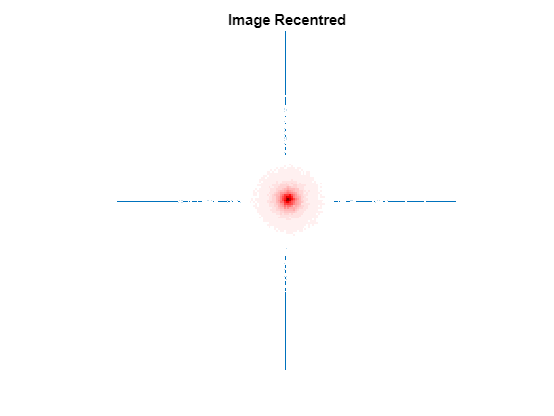

res = length(image_cropped(:, :, 1));

i =6;

change_x =-1;   % -1
change_y =-1;   % -1

image_cropped(:, :, i) = max(image_cropped(:, :, i), 0);

image_centred(:, :, i) = circshift(image_cropped(:, :, i), [change_y, change_x]);
% image_centred(:, :, i) = rescale(image_centred(:, :, i));
showim(image_centred(:, :, i), 1)
shading flat
title("Image Recentred")
axis('equal')
axis('tight')

crosshair = drawcrosshair("LineWidth", 0.5, Position=[res/2, res/2]);

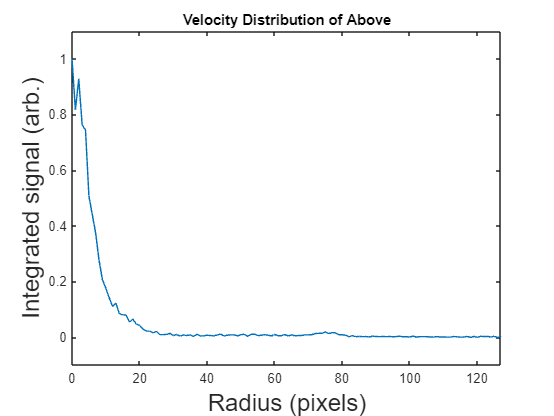

% set(gcf, 'Visible', 'on')

[v_real,r_real] = velocity_dist(image_centred(:, :, i), res);
plot(r_real, v_real)
xlim([0, max(r_real)])
ylim([-0.1, 1.1])
xlabel("Radius (pixels)", "FontSize", 18)
ylabel("Integrated signal (arb.)", "FontSize", 18)
title("Velocity Distribution of Above")

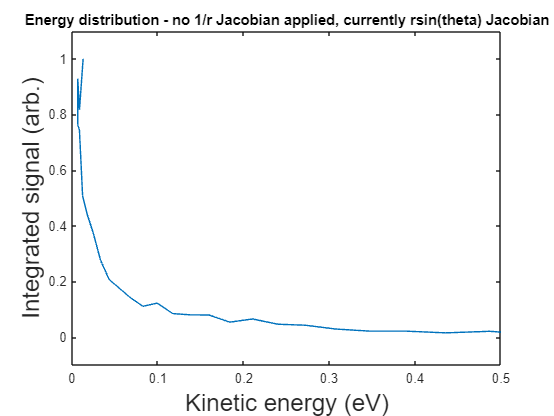



if i == 1
    % for 16 eV data
    energy = 0.0048 - 2.33326E-4 * r_real + 1.66154E-4 * r_real.^2;

elseif i == 2 || i == 5 || i == 8
    % for 20 eV data
    energy = -4.2879E-4 + 6.72761E-5 * r_real + 1.60121E-4 * r_real.^2;

elseif i == 3 || i == 6 || i == 9
    % for 100 eV data
    energy = 0.01295 - 0.00542 * r_real + 0.00121 * r_real.^2 - 3.51159E-5 * r_real.^3 + 1.02815E-6 * r_real.^4;

elseif i == 4 || i == 7
    % for 13 eV data
    energy = 0.0048 - 2.33326E-4 * r_real + 1.66154E-4 * r_real.^2;
end


figure()
plot(energy, v_real)
xlim([0, 0.5])
ylim([-0.1, 1.1])
xlabel("Kinetic energy (eV)", "FontSize", 18)
ylabel("Integrated signal (arb.)", "FontSize", 18)
title("Energy distribution - no 1/r Jacobian applied, currently rsin(theta) Jacobian")

Rotate image (to change symmetry axis)

% image_centred(:, :, i) = rot90(image_centred(:, :, i));
% 
% showim(image_centred(:, :, i), 1)
% shading flat
% title("Centered Image Rotated")


Symmetrise data to improve statistics and erase detector dead spot

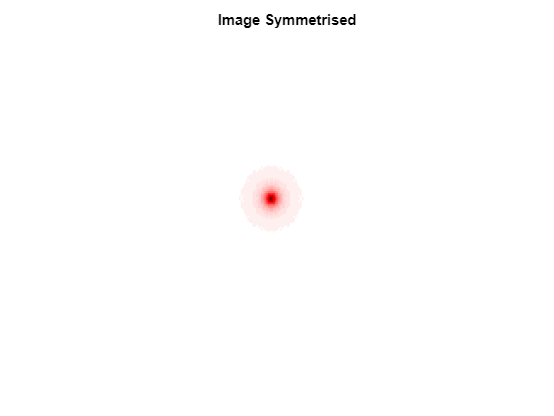

image_quadrant = image_centred(:, :, i);

% NOTE: don't use bottom right quadrant

image_quadrant_bottomleft =  image_quadrant(1:(res/2), 1:(res/2));
image_quadrant_topright =  image_quadrant((res/2+1):end, (res/2+1):end);
% image_quadrant_bottomright = image_quadrant(1:(res/2), (res/2+1):end);
image_quadrant_bottomright = zeros(90, 90);     % see above comment
image_quadrant_topleft = image_quadrant((res/2+1):end, 1:(res/2));


% bottomleft
input = image_quadrant_bottomleft;
flipped_v = flip(input, 2);
added = cat(2, input, flipped_v);
flipped = flip(added, 1);
added = cat(1, added, flipped);
image_centred_using_quadrant_bottomleft = added;

% topright
input = image_quadrant_topright;
flipped_v = flip(input, 2);
added = cat(2, flipped_v, input);
flipped = flip(added, 1);
added = cat(1, flipped, added);
image_centred_using_quadrant_topright = added;

% bottomright
input = image_quadrant_bottomright;
flipped_v = flip(input, 2);
added = cat(2, flipped_v, input);
flipped = flip(added, 1);
added = cat(1, added, flipped);
image_centred_using_quadrant_bottomright = added;

% topleft
input = image_quadrant_topleft;
flipped_v = flip(input, 1);
added = cat(1, flipped_v, input);
flipped = flip(added, 2);
added = cat(2, added, flipped);
image_centred_using_quadrant_topleft = added;


image_symmetrised = image_centred_using_quadrant_bottomleft + image_centred_using_quadrant_topright + image_centred_using_quadrant_bottomright + image_centred_using_quadrant_topleft;
image_symmetrised = rescale(image_symmetrised);

showim(image_symmetrised, 1)
shading flat
title("Image Symmetrised")

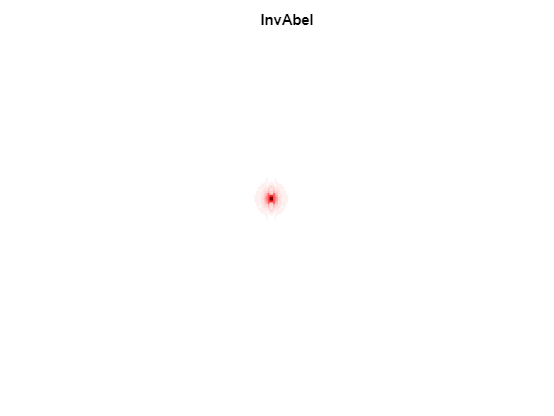


showim(InvAbel(image_symmetrised), 1)
shading flat
title("InvAbel")

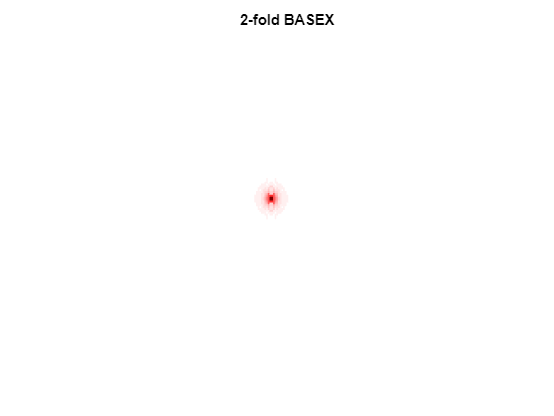


showim(BASEX(image_symmetrised, "2-fold", 0), 1);
shading flat
title("2-fold BASEX")

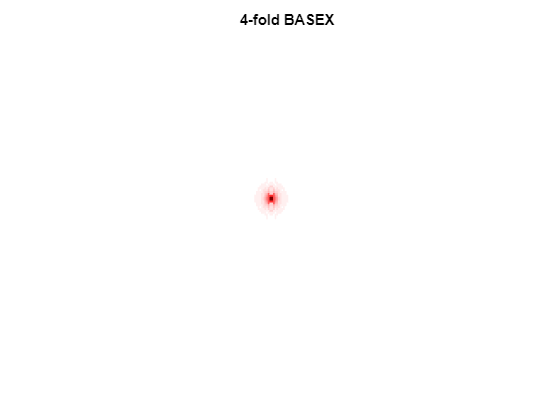


showim(BASEX(image_symmetrised, "4-fold", 0), 1);
shading flat
title("4-fold BASEX")

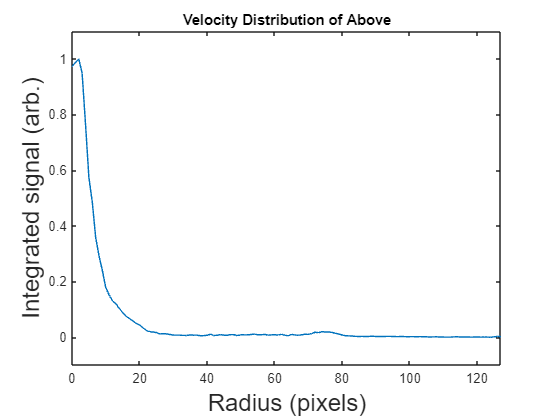



[v_real, r_real] = velocity_dist(image_symmetrised, res);
plot(r_real, v_real)
xlim([0, max(r_real)])
ylim([-0.1, 1.1])
xlabel("Radius (pixels)", "FontSize", 18)
ylabel("Integrated signal (arb.)", "FontSize", 18)
title("Velocity Distribution of Above")

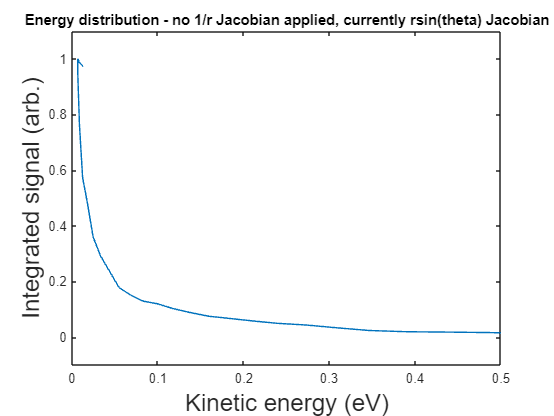


if i == 1
    % for 16 eV data
    energy = 0.0048 - 2.33326E-4 * r_real + 1.66154E-4 * r_real.^2;

elseif i == 2 || i == 5 || i == 8
    % for 20 eV data
    energy = -4.2879E-4 + 6.72761E-5 * r_real + 1.60121E-4 * r_real.^2;

elseif i == 3 || i == 6 || i == 9
    % for 100 eV data
    energy = 0.01295 - 0.00542 * r_real + 0.00121 * r_real.^2 - 3.51159E-5 * r_real.^3 + 1.02815E-6 * r_real.^4;

elseif i == 4 || i == 7
    % for 13 eV data
    energy = 0.0048 - 2.33326E-4 * r_real + 1.66154E-4 * r_real.^2;
end


figure()
plot(energy, v_real)
xlim([0, 0.5])
ylim([-0.1, 1.1])
xlabel("Kinetic energy (eV)", "FontSize", 18)
ylabel("Integrated signal (arb.)", "FontSize", 18)
title("Energy distribution - no 1/r Jacobian applied, currently rsin(theta) Jacobian")

## Prepare network training data

newsection("Prepare network training data");

---------------------------------------------------------------------------
Prepare network training data
---------------------------------------------------------------------------


Set up coordinate system

x = linspace(-1, 1, res);
y = linspace(-1, 1, res);
[X, Y] = meshgrid(x, y);
R = sqrt(X.^2 + Y.^2);


Generate simulated data 

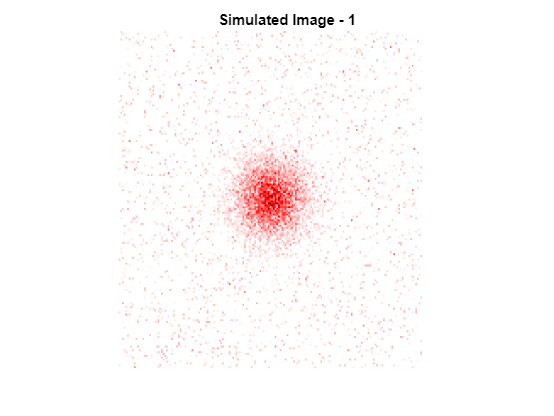

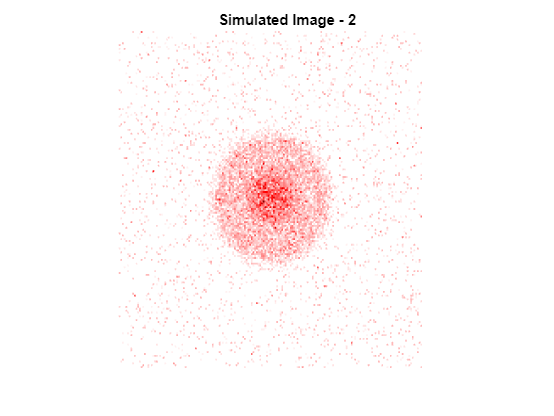

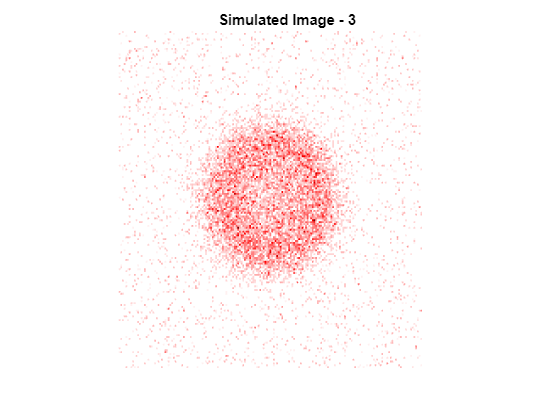

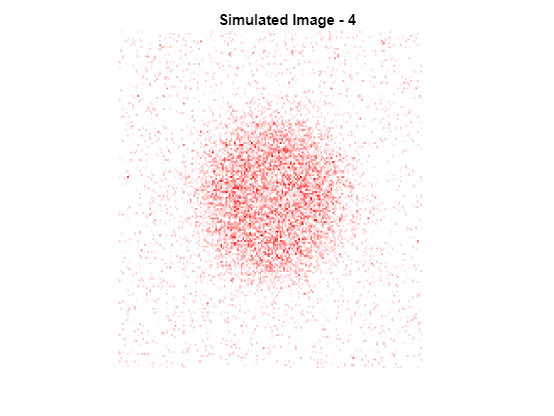

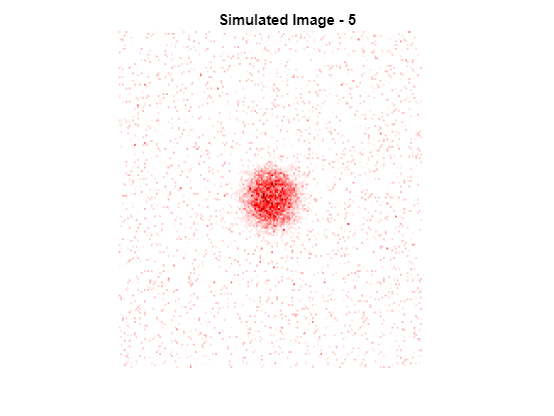

N = 2000;     % number of distributions to simulate

threshold = 0.0001;     % make sure nothing exceeds the edges of the grid

I = zeros(res, res, N);
I_Abel = zeros(res, res, N);
I_Abel_sampled = zeros(res, res, N);
I_Abel_withnoise = zeros(res, res, N);

for k = 1:N

    check = 0;
    while check == 0

        num_rings = randi(2);

        % W1 = W1_fit + (-1)^(round(rand)) * (0.2*rand);
        % R1 = R0_1_fit + (-1)^(round(rand)) * (0.3*rand);
        % A1 = A1_fit + (-1)^(round(rand)) * (0.2*rand);

        W1 = (0.2 - 0.005)*rand + 0.005;
        R1 = (0.3 + 0.2)*rand - 0.1;
        A1 = (1 - 0.1)*rand + 0.1;

        W2 = (0.2 - 0.005)*rand + 0.005;  
        R2 = (0.3 + 0.2)*rand - 0.1;
        A2 = (1 - 0.1)*rand + 0.1;

        if R1 < 0
            R1 = 0;
        end

        coeffs.num_rings = num_rings;

        if num_rings == 1
            A2 = 0;
            R2 = 0;
            W2 = 0;
        end

        coeffs.W1(k) = W1;
        coeffs.R1(k) = R1;
        coeffs.A1(k) = A1;

        coeffs.W2(k) = W2;
        coeffs.R2(k) = R2;
        coeffs.A2(k) = A2;


        I(:, :, k) = A1*exp(-((R - R1)/W1).^2) + A2*exp(-((R - R2)/W2).^2);

        I_Abel(:, :, k) = Abel(I(:, :, k));

        if any(I_Abel(1,:,k) > threshold) || any(I_Abel(:,1,k) > threshold) || any(I_Abel(end,:,k) > threshold) || any(I_Abel(:,end,k) > threshold) || any(I_Abel(:) < 0)
            check = 0;
        else
            check = 1;
        end

        I(:, :, k) = rescale(I(:, :, k));
        I_Abel(:, :, k) = rescale(I_Abel(:, :, k));

        I_Abel(:, :, k) = I_Abel(:, :, k)/sum(I_Abel(:, :, k), 'all');
        counts_present = 10^4;
        counts = ((1-0.1)*rand + 0.1)*I_Abel(:, :, k)*counts_present;
        I_Abel_sampled(:, :, k) = poissrnd(counts, height(I_Abel(:, :, k)), length(I_Abel(:, :, k)));

        I_Abel_sampled(:, :, k) = rescale(I_Abel_sampled(:, :, k));

        lambda = (0.13 - 0.08)*rand + 0.08;

        noise = poissrnd(lambda, [res, res]);
        noise_intensity = ones(size(noise))*0.2.*rand(180);
        background = noise_intensity.*noise;

        I_Abel_withnoise(:, :, k) = I_Abel_sampled(:, :, k) + background;


        I_Abel(:, :, k) = rescale(I_Abel(:, :, k));
        I_Abel_withnoise(:, :, k) = rescale(I_Abel_withnoise(:, :, k));

        
        coeffs.lambda = lambda;
        coeffs.counts_present = counts_present;


    end
    

end



for k = 1:5

    % showim(I(:, :, k), 1)
    % title(k + " - Central Slice")
    % shading flat
    % 
    % showim(I_Abel(:, :, k), 1)
    % title(k + " - Abel")
    % shading flat
    % 
    % showim(I_Abel_sampled(:, :, k), 1)
    % title(k + " - Abel sampled @ 10^4 counts")
    % shading flat

    showim(I_Abel_withnoise(:, :, k), 1)
    title("Simulated Image - " + k)
    shading flat

end

Take quadrant and save images for network usage

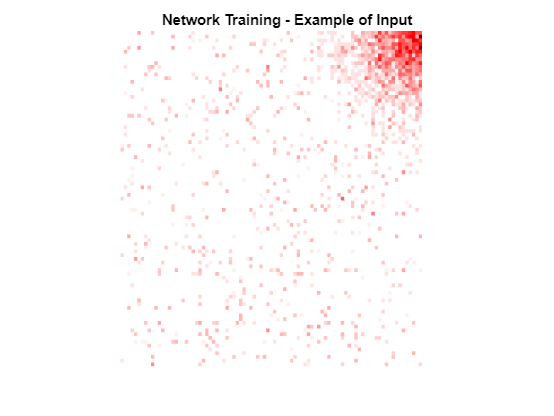

I_Abel_withnoise_quadrant = I_Abel_withnoise(1:(res/2), 1:(res/2), :);
I_Abel_quadrant = I_Abel(1:(res/2), 1:(res/2), :);

showim(I_Abel_withnoise_quadrant(:, :, 1), 1)
shading flat
title("Network Training - Example of Input")

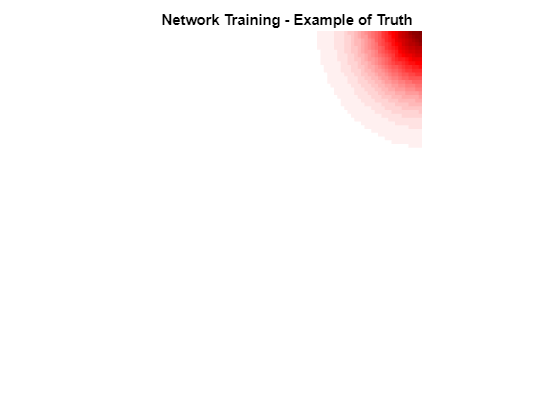


showim(I_Abel_quadrant(:, :, 1), 1)
shading flat
title("Network Training - Example of Truth")


save("noisy", "I_Abel_withnoise_quadrant")
save("noisefree", "I_Abel_quadrant")
save("coeffs", "coeffs")


## Assess network validation set

newsection("Assess network validation set");

---------------------------------------------------------------------------
Assess network validation set
---------------------------------------------------------------------------


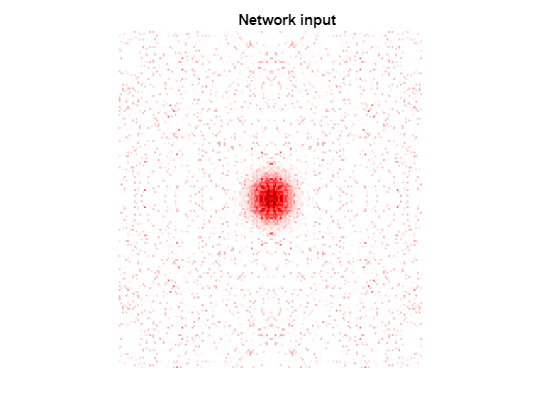

% set the run number, this is indicated by the gdrive file
run_no = 6;

% load all aspects of that run
load("G:\My Drive\PhD\denoise_oxford\run_"+run_no+"\results.mat");
load("G:\My Drive\PhD\denoise_oxford\run_"+run_no+"\history.mat");
noisefree_raw = load("G:\My Drive\PhD\denoise_oxford\run_"+run_no+"\noisefree.mat");
noisy_raw = load("G:\My Drive\PhD\denoise_oxford\run_"+run_no+"\noisy.mat");
% images_mat = load("G:\My Drive\PhD\deblur\run_"+run_no+"\images.mat");
% coeffs = load("G:\My Drive\PhD\deblur\run_"+run_no+"\coeffs.mat");
% coeffs = coeffs.coeffs;

noisefree = noisefree_raw.I_Abel_quadrant;
noisy = noisy_raw.I_Abel_withnoise_quadrant;

% convert the network_output in the correct dimensionality
network_output = results.predictions;
network_output = permute(network_output, [2, 3, 1]);

% choose image to analyse
N = 8;
N_val = N;


% use 4-fold symmetry to assemble full images (fs stands for full size!)
noisy_fs = flipcat_4fold_bl(noisy(:,:,N));
showim(noisy_fs, 1)
title("Network input")
shading flat

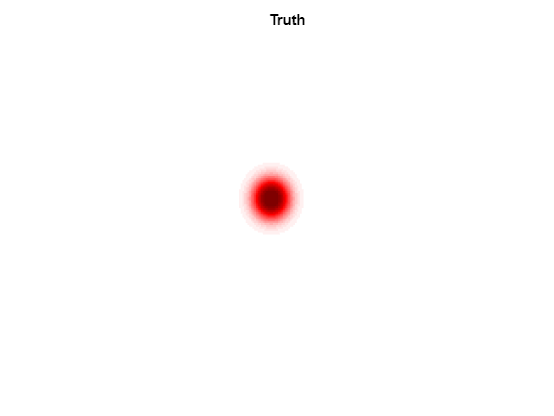


noisefree_fs = flipcat_4fold_bl(noisefree(:,:,N));
showim(noisefree_fs, 1)
title("Truth")
shading flat

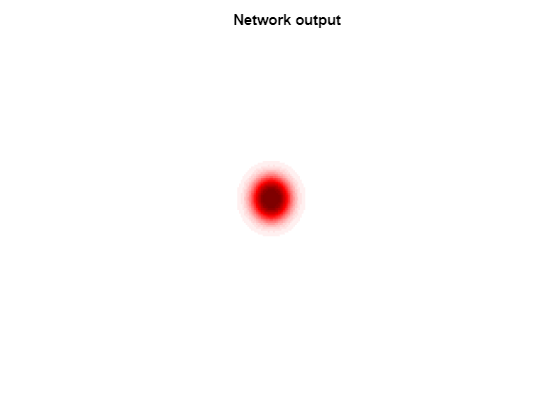


network_output_fs = flipcat_4fold_bl(network_output(:, :, N_val));
showim(network_output_fs, 1)
title("Network output")
shading flat

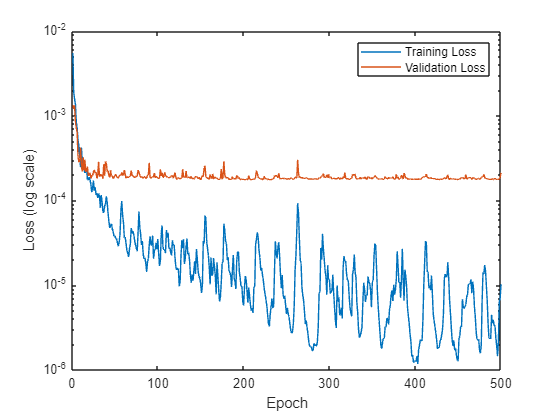


% residual = network_output_fs - noisefree_fs;
% showim(residual, 1)
% title("Residual")
% colorbar
% clim([-1, 1])
% shading flat


% rmse = sqrt(mean((noisefree_fs(:)-network_output_fs(:)).^2));
% rmse_network = sqrt(mean((noisy_fs(:)-network_output_fs(:)).^2));


% -----------------------------------------------------------------------------------------------

% plot the loss
figure()
semilogy(loss)
hold on
semilogy(val_loss)
legend("Training Loss", "Validation Loss")
xlabel("Epoch")
ylabel("Loss (log scale)")

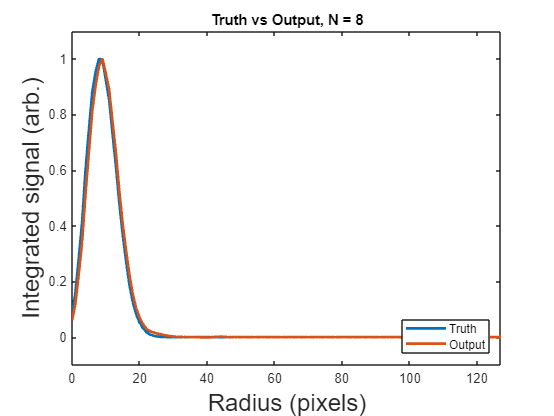


% -----------------------------------------------------------------------------------------------

% inverse Abel invert (invAbel) the network output
% inverted_output = InvAbel(network_output_fs);
% showim(inverted_output, 1);
% title("InvAbel  - Network output")
% shading flat

% integrate network output over all radii and angles

[v_output, r] = velocity_dist(network_output_fs, 180);

% -----------------------------------------------------------------------------------------------

% invAbel the network input
% inverted_network_input = InvAbel(noisy_fs);
% showim(inverted_network_input, 1)
% title("InvAbel - Network input")
% shading flat

%integrate network input over all radii and angles
[v_input, r] = velocity_dist(noisy_fs, 180);
% -----------------------------------------------------------------------------------------------

% inverted_truth = InvAbel(noisefree_fs);
% showim(inverted_truth, 1);
% title("InvAbel - Truth")

[v_truth, r] = velocity_dist(noisefree_fs, 180);

% -----------------------------------------------------------------------------------------------




% plot the velocity distributions

% % network input
% figure()
% plot(r, v_input, "LineWidth", 2)
% title("Velocity distribution - Network input")
% xlim([0, max(r)])
% % xlim([0, 40])
% ylim([-0.1, 1.1])
% xlabel("Radius (pixels)", "FontSize", 18)
% ylabel("Integrated signal (arb.)", "FontSize", 18)


% %truth
% figure()
% plot(r, v_truth, "LineWidth", 2)
% title("Velocity distribution - Truth")
% xlim([0, max(r)])
% ylim([-0.1, 1.1])
% xlabel("Radius (pixels)", "FontSize", 18)
% ylabel("Integrated signal (arb.)", "FontSize", 18)


% % network output
% figure()
% plot(r, v_output, "LineWidth", 2)
% title("Velocity distribution - Network output")
% xlim([0, max(r)])
% ylim([-0.1, 1.1])
% xlabel("Radius (pixels)", "FontSize", 18)
% ylabel("Integrated signal (arb.)", "FontSize", 18)


% truth vs output
figure()
plot(r, v_truth, "LineWidth", 2)
hold on
plot(r, v_output, "LineWidth", 2)
title("Truth vs Output, N = " + N)
xlim([0, max(r)])
ylim([-0.1, 1.1])
xlabel("Radius (pixels)", "FontSize", 18)
ylabel("Integrated signal (arb.)", "FontSize", 18)
legend("Truth", "Output", "location", "southeast")

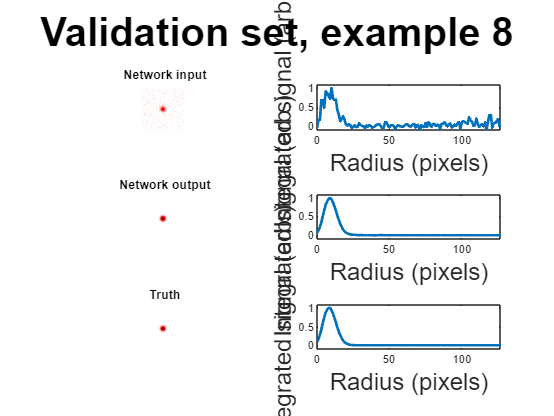




subplot(321)
showim_subplot(noisy_fs, 1)
title("Network input")
shading flat

subplot(322)
[v_input, r] = velocity_dist(noisy_fs, 180);
plot(r, v_input, "LineWidth", 2)
xlim([0, max(r)])
ylim([-0.1, 1.1])
xlabel("Radius (pixels)", "FontSize", 18)
ylabel("Integrated signal (arb.)", "FontSize", 18)
% title("Input")

subplot(323)
network_output_fs = flipcat_4fold_bl(network_output(:, :, N));
showim_subplot(network_output_fs, 1)
title("Network output")
shading flat

subplot(324)
[v_output, r] = velocity_dist(network_output_fs, 180);
plot(r, v_output, "LineWidth", 2)
xlim([0, max(r)])
ylim([-0.1, 1.1])
xlabel("Radius (pixels)", "FontSize", 18)
ylabel("Integrated signal (arb.)", "FontSize", 18)
% title("Output")

subplot(325)
showim_subplot(noisefree_fs, 1)
title("Truth")
shading flat

subplot(326)
[v_truth, r] = velocity_dist(noisefree_fs, 180);
plot(r, v_truth, "LineWidth", 2)
xlim([0, max(r)])
ylim([-0.1, 1.1])
xlabel("Radius (pixels)", "FontSize", 18)
ylabel("Integrated signal (arb.)", "FontSize", 18)
% title("Truth")


% sgtitle(frames(N) + " Frames", "FontWeight", "bold", "FontSize", 30)
sgtitle("Validation set, example " + N, "FontWeight", "bold", "FontSize", 30)

## Assess network output, no truth shown

newsection("Assess network output, no truth shown");

---------------------------------------------------------------------------
Assess network output, no truth shown
---------------------------------------------------------------------------


% filename = ["16eV_CF2I+_centred", "20eV_CF2I+_centred", "100eV_CF2I+_centred", "100eV_CF2I+_centred_symmetrised", "100eV_CF2I+_centred_sampled_old", "100eV_CF2I+_centred_sampled_by_me_10^4", "100eV_CF2I+_centred_sampled_by_Alex", "100eV_CF2I+_centred_sampled_by_Alex_normalised", "100eV_CF2I+_centred_sampled_by_Alex_normalised_symmetrised"];

% i =2;

run_no = 8;

load("G:\My Drive\PhD\denoise_oxford\run_"+ run_no +"\" + "\results_process.mat");
load("G:\My Drive\PhD\denoise_oxford\run_"+ run_no +"\" + "\noisy_process.mat");
% load("G:\My Drive\PhD\denoise_oxford\run_"+ run_no +"\" + "\noisy_process_real.mat");


% load("G:\My Drive\PhD\denoise_oxford\run_"+ run_no +"\" + "All fragments, different energies" +"\results_process.mat");
% % load("G:\My Drive\PhD\denoise_oxford\run_"+ run_no +"\" + "\noisy_process.mat");
% load("G:\My Drive\PhD\denoise_oxford\run_"+ run_no +"\" + "All fragments, different energies" + "\noisy_process.mat");


network_output = results.predictions;
network_output = permute(network_output, [2, 3, 1]);

network_input = results.input;
network_input = permute(network_input, [2, 3, 1]);


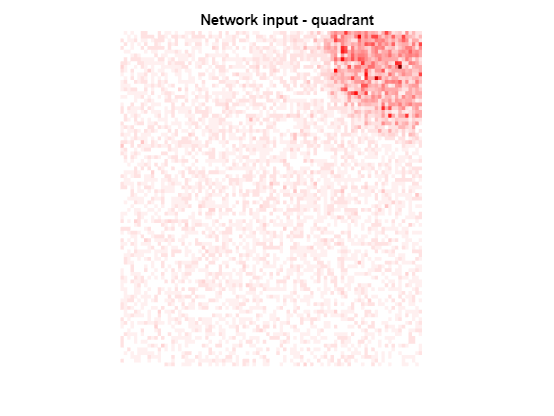

N = 5;

process_quadrant = network_input;

showim(process_quadrant(:, :, N), 1);
title("Network input - quadrant")
shading flat

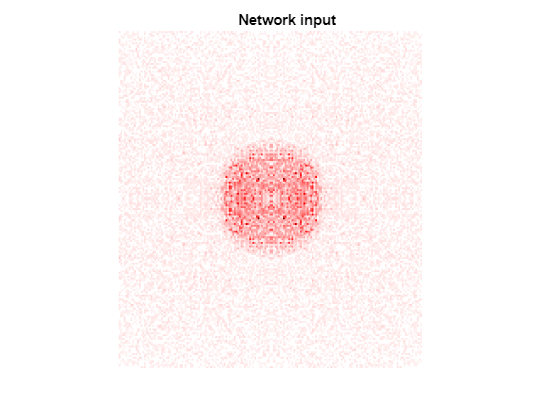


noisy_fs = flipcat_4fold_bl(process_quadrant(:, :, N));
showim(noisy_fs, 1)
title("Network input")
shading flat

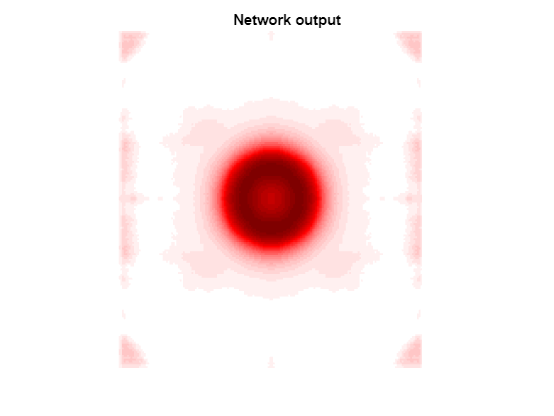


network_output_fs = flipcat_4fold_bl(network_output(:, :, N));
showim(network_output_fs, 1)
title("Network output")
shading flat

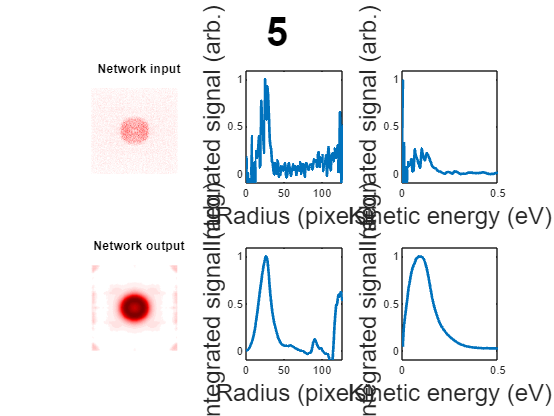



% showim(InvAbel(noisy_fs), 1)
% title("Network input")
% shading flat
% 
% showim(InvAbel(network_output_fs), 1)
% title("Network output")
% shading flat



[v_input, r] = velocity_dist(noisy_fs, 180);
% plot(r, v_input, "LineWidth", 2)
% xlim([0, max(r)])
% ylim([-0.1, 1.1])
% xlabel("Radius (pixels)", "FontSize", 18)
% ylabel("Integrated signal (arb.)", "FontSize", 18)
% title("Input")

[v_output, r] = velocity_dist(network_output_fs, 180);
% plot(r, v_output, "LineWidth", 2)
% xlim([0, max(r)])
% ylim([-0.1, 1.1])
% xlabel("Radius (pixels)", "FontSize", 18)
% ylabel("Integrated signal (arb.)", "FontSize", 18)
% title("Output")

% plot(r, v_input)
% hold on
% plot(r, v_output)
% hold off
% xlim([0, max(r)])
% ylim([-0.1, 1.1])
% xlabel("Radius (pixels)")
% ylabel("Integrated signal (arb.)")
% title("Truth vs Output, N = " + N)
% legend("Input", "Output")




% plot above but in energy 
if N == 1 | N == 2 | N == 3
    % for 100 eV data
    energy = 0.01295 - 0.00542 * r_real + 0.00121 * r_real.^2 - 3.51159E-5 * r_real.^3 + 1.02815E-6 * r_real.^4;

elseif N == 4 | N == 5
    % for all 13 eV data
    energy = 0.0048 - 2.33326E-4 * r_real + 1.66154E-4 * r_real.^2;

elseif N == 6
    % for 16 eV data
    energy = 1.69975E-5 + 3.42065E-5 * r_real + 1.68763E-4 * r_real.^2

elseif N == 7 | N == 8 | N == 9
    % for 20 eV data
    energy = -4.2879E-4 + 6.72761E-5 * r_real + 1.60121E-4 * r_real.^2;

end


v_input_energy = v_input./r_real;
v_output_energy = v_output./r_real;

% v_input_energy = v_input_energy/max(v_input_energy);
% v_output_energy = v_output_energy/max(v_output_energy);

[peaks_input, locs_input] = findpeaks(v_input_energy);
[peaks_output, locs_output] = findpeaks(v_output_energy);

peaks_input(isinf(peaks_input)) = 0;
peaks_output(isinf(peaks_output)) = 0;

idx1 = find(peaks_input == max(peaks_input));
idx2 = find(peaks_output == max(peaks_output));

v_input_energy = v_input_energy/v_input_energy(locs_input(idx1));
v_output_energy = v_output_energy/v_output_energy(locs_output(idx2));

v_input_energy(isinf(v_input_energy)) = NaN;
v_output_energy(isinf(v_output_energy)) = NaN;

v_input_energy = v_input_energy/max(v_input_energy);
v_output_energy = v_output_energy/max(v_output_energy);

% figure()
% plot(energy, v_input, "LineWidth", 2)
% xlim([0, 0.5])
% ylim([-0.1, 1.1])
% xlabel("Kinetic energy (eV)", "FontSize", 18)
% ylabel("Integrated signal (arb.)", "FontSize", 18)
% title("Input")
% 
% figure()
% plot(energy, v_output, "LineWidth", 2)
% xlim([0, 0.5])
% ylim([-0.1, 1.1])
% xlabel("Kinetic energy (eV)", "FontSize", 18)
% ylabel("Integrated signal (arb.)", "FontSize", 18)
% title("Output")



% figure()
% plot(energy, v_input_energy, "LineWidth", 2)
% xlim([0, 0.5])
% ylim([-0.1, 1.1])
% xlabel("Kinetic energy (eV)", "FontSize", 18)
% ylabel("Integrated signal (arb.)", "FontSize", 18)
% title("Input")
% 
% figure()
% plot(energy, v_output_energy, "LineWidth", 2)
% xlim([0, 0.5])
% ylim([-0.1, 1.1])
% xlabel("Kinetic energy (eV)", "FontSize", 18)
% ylabel("Integrated signal (arb.)", "FontSize", 18)
% title("Output")




subplot(231)
showim_subplot(noisy_fs, 1)
title("Network input")
shading flat

subplot(232)
[v_input, r] = velocity_dist(noisy_fs, 180);
plot(r, v_input, "LineWidth", 2)
xlim([0, max(r)])
ylim([-0.1, 1.1])
xlabel("Radius (pixels)", "FontSize", 18)
ylabel("Integrated signal (arb.)", "FontSize", 18)
% title("Input")

subplot(233)
plot(energy, v_input_energy, "LineWidth", 2)
xlim([0, 0.5])
ylim([-0.1, 1.1])
xlabel("Kinetic energy (eV)", "FontSize", 18)
ylabel("Integrated signal (arb.)", "FontSize", 18)
% title("Input")


subplot(234)
network_output_fs = flipcat_4fold_bl(network_output(:, :, N));
showim_subplot(network_output_fs, 1)
title("Network output")
shading flat

subplot(235)
[v_output, r] = velocity_dist(network_output_fs, 180);
plot(r, v_output, "LineWidth", 2)
xlim([0, max(r)])
ylim([-0.1, 1.1])
xlabel("Radius (pixels)", "FontSize", 18)
ylabel("Integrated signal (arb.)", "FontSize", 18)
% title("Output")

subplot(236)
plot(energy, v_output_energy, "LineWidth", 2)
xlim([0, 0.5])
ylim([-0.1, 1.1])
xlabel("Kinetic energy (eV)", "FontSize", 18)
ylabel("Integrated signal (arb.)", "FontSize", 18)
% title("Output")


% sgtitle(frames(N) + " Frames", "FontWeight", "bold", "FontSize", 30)
sgtitle(N, "FontWeight", "bold", "FontSize", 30)

## Artificially sample real data

newsection("Artificially sample real data");

---------------------------------------------------------------------------
Artificially sample real data
---------------------------------------------------------------------------


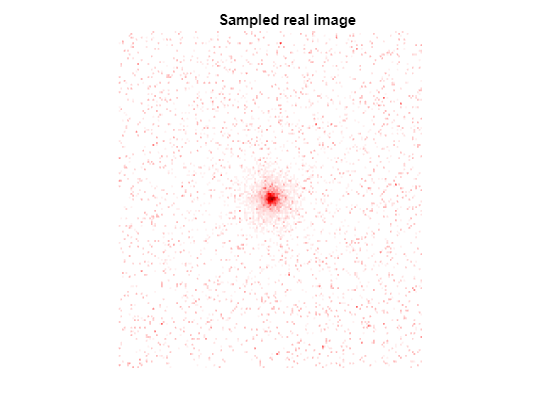

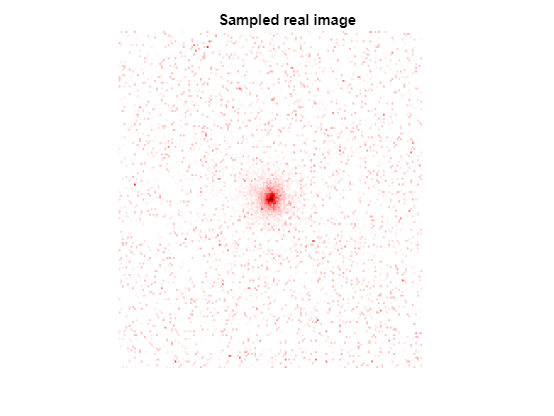

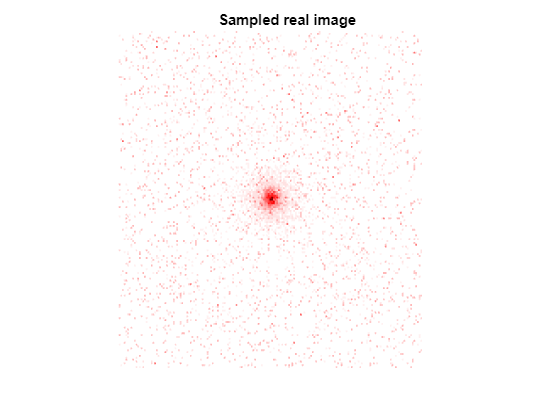

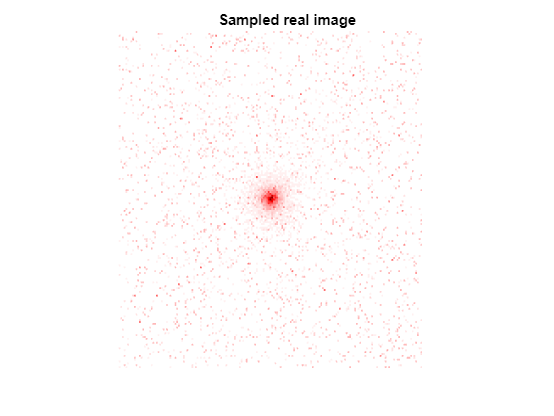

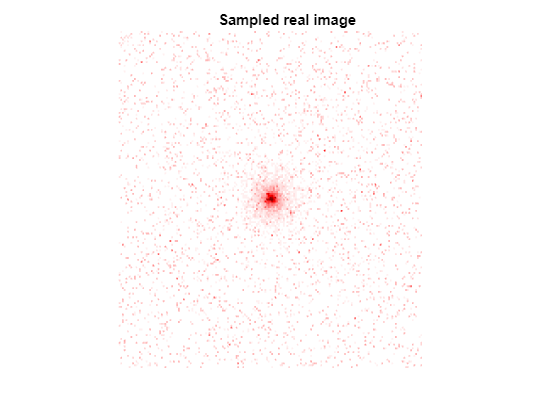

clear process_quadrant;

for j = 1:5

    real_image_sampled = image_symmetrised;
    real_image_sampled = real_image_sampled/sum(real_image_sampled, 'all');
    counts_present = 1*10^4;        % previously 2e3

    counts = real_image_sampled*counts_present;
    real_image_sampled = poissrnd(counts, height(real_image_sampled), length(real_image_sampled));
    % counts_in_image = sum(real_image_sampled, 'all')

    real_image_sampled = rescale(real_image_sampled);

    lambda = (0.11 - 0.08)*rand + 0.08;

    noise = poissrnd(lambda, [res, res]);
    noise_intensity = ones(size(noise))*0.2.*rand(180);
    background = noise_intensity.*noise;

    real_image_sampled = real_image_sampled + background;

    real_image_sampled = rescale(real_image_sampled);

    showim(real_image_sampled, 1)
    shading flat
    title("Sampled real image")

    process_quadrant(:, :, j) = real_image_sampled(1:(res/2), 1:(res/2), :);
    % process_quadrant(:, :, 2) = real_image_sampled(1:(res/2), 1:(res/2) :);      % need if only one image

    % showim(process_quadrant(:, :, 1), 1)
    % shading flat
    % title("Quadrant of above")

end


save("noisy_process_real", "process_quadrant")


## Assess data with a relevant truth

newsection("Assess data with a relevant truth");

---------------------------------------------------------------------------
Assess data with a relevant truth
---------------------------------------------------------------------------


run_no = 7;

real_or_art = ["Real sampled", "Artificially sampled"];
fragment = ["CF2I+", "CF3+", "I+"];

ch1 = real_or_art(2);
ch2 = fragment(2);

load("G:\My Drive\PhD\denoise_oxford\run_"+ run_no +"\" + ch1 + " " + ch2 + "\results_process.mat");
load("G:\My Drive\PhD\denoise_oxford\run_"+ run_no +"\" + ch1 + " " + ch2 + "\noisy_process_real.mat");



load("G:\My Drive\PhD\denoise_oxford\run_"+ run_no +"\" + "\results_process.mat");
load("G:\My Drive\PhD\denoise_oxford\run_"+ run_no +"\" + "\noisy_process_real.mat");

network_output = results.predictions;
network_output = permute(network_output, [2, 3, 1]);

network_input = results.input;
network_input = permute(network_input, [2, 3, 1]);


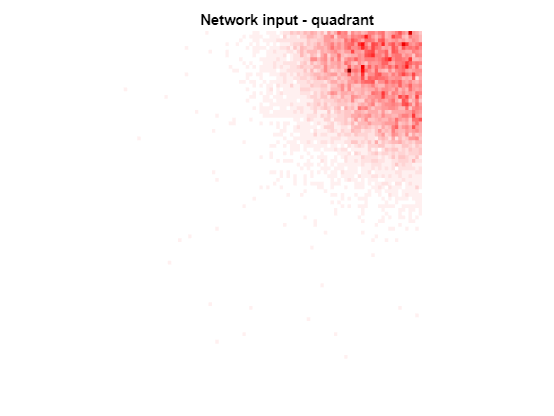

N = 9;

process_quadrant = network_input;

showim(process_quadrant(:, :, N), 1);
title("Network input - quadrant")
shading flat

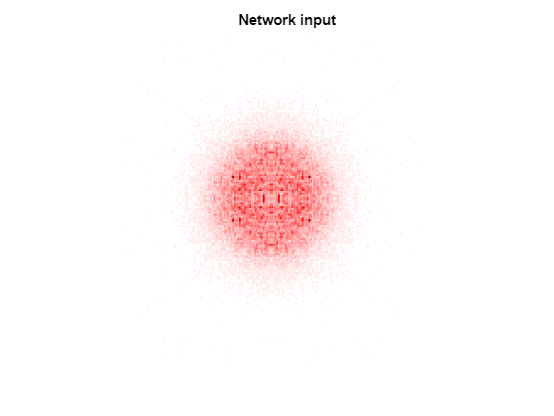


noisy_fs = flipcat_4fold_bl(process_quadrant(:, :, N));
showim(noisy_fs, 1)
title("Network input")
shading flat

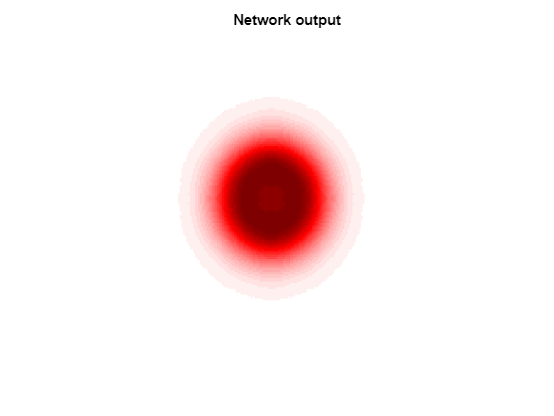


network_output_fs = flipcat_4fold_bl(network_output(:, :, N));
showim(network_output_fs, 1)
title("Network output")
shading flat

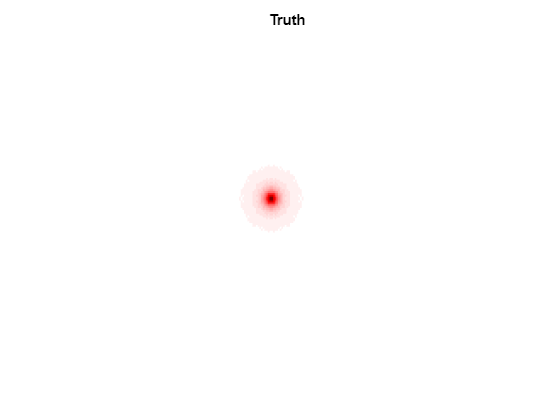


noisefree_fs = image_symmetrised;
showim(noisefree_fs, 1)
title("Truth")
shading flat

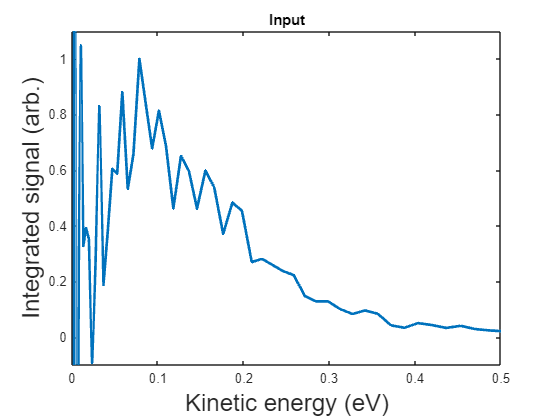



% showim(InvAbel(noisy_fs), 1)
% title("Network input")
% shading flat
% 
% showim(InvAbel(network_output_fs), 1)
% title("Network output")
% shading flat



[v_input, r] = velocity_dist(noisy_fs, 180);
% plot(r, v_input, "LineWidth", 2)
% xlim([0, max(r)])
% ylim([-0.1, 1.1])
% xlabel("Radius (pixels)", "FontSize", 18)
% ylabel("Integrated signal (arb.)", "FontSize", 18)
% title("Input")

[v_output, r] = velocity_dist(network_output_fs, 180);
% plot(r, v_output, "LineWidth", 2)
% xlim([0, max(r)])
% ylim([-0.1, 1.1])
% xlabel("Radius (pixels)", "FontSize", 18)
% ylabel("Integrated signal (arb.)", "FontSize", 18)
% title("Output")

[v_truth, r] = velocity_dist(noisefree_fs, 180);
% plot(r, v_truth, "LineWidth", 2)
% xlim([0, max(r)])
% ylim([-0.1, 1.1])
% xlabel("Radius (pixels)", "FontSize", 18)
% ylabel("Integrated signal (arb.)", "FontSize", 18)
% title("Truth")



% plot(r, v_input)
% hold on
% plot(r, v_output)
% hold off
% xlim([0, max(r)])
% ylim([-0.1, 1.1])
% xlabel("Radius (pixels)")
% ylabel("Integrated signal (arb.)")
% title("Input vs Output - N = " + N)
% legend("Input", "Output")




% plot above but in energy 
if N == 1 | N == 2 | N == 3
    % for 100 eV data
    energy = 0.01295 - 0.00542 * r_real + 0.00121 * r_real.^2 - 3.51159E-5 * r_real.^3 + 1.02815E-6 * r_real.^4;

elseif N == 4 | N == 5
    % for all 13 eV data
    energy = 0.0048 - 2.33326E-4 * r_real + 1.66154E-4 * r_real.^2;

elseif N == 6
    % for 16 eV data
    energy = 1.69975E-5 + 3.42065E-5 * r_real + 1.68763E-4 * r_real.^2

elseif N == 7 | N == 8 | N == 9
    % for 20 eV data
    energy = -4.2879E-4 + 6.72761E-5 * r_real + 1.60121E-4 * r_real.^2;

end


v_input_energy = v_input./r_real;
v_output_energy = v_output./r_real;
v_truth_energy = v_truth./r_real;

% v_input_energy = v_input_energy/0.18;
% v_input_energy = v_input_energy/max(v_input_energy);
% v_output_energy = v_output_energy/max(v_output_energy);

[peaks_input, locs_input] = findpeaks(v_input_energy);
% [peaks_output, locs_output] = findpeaks(v_output_energy);
[peaks_truth, locs_truth] = findpeaks(v_truth_energy);

peaks_input(isinf(peaks_input)) = 0;
% peaks_output(isinf(peaks_output)) = 0;
peaks_truth(isinf(peaks_truth)) = 0;
% 
idx1 = find(peaks_input == max(peaks_input));
% idx2 = find(peaks_output == max(peaks_output));
idx3 = find(peaks_truth == max(peaks_truth));

v_input_energy = v_input_energy/v_input_energy(locs_input(idx1));
% v_output_energy = v_output_energy/v_output_energy(locs_output(idx2));
% v_truth_energy = v_truth_energy/v_truth_energy(locs_output(idx3));

v_input_energy(isinf(v_input_energy)) = NaN;
v_output_energy(isinf(v_output_energy)) = NaN;
v_truth_energy(isinf(v_truth_energy)) = NaN;

v_input_energy = v_input_energy/max(v_input_energy);
v_output_energy = v_output_energy/max(v_output_energy);
v_truth_energy = v_truth_energy/max(v_truth_energy);


v_input_energy = v_input_energy/0.2568;

% figure()
% plot(energy, v_input, "LineWidth", 2)
% xlim([0, 0.5])
% ylim([-0.1, 1.1])
% xlabel("Kinetic energy (eV)", "FontSize", 18)
% ylabel("Integrated signal (arb.)", "FontSize", 18)
% title("Input")
% 
% figure()
% plot(energy, v_output, "LineWidth", 2)
% xlim([0, 0.5])
% ylim([-0.1, 1.1])
% xlabel("Kinetic energy (eV)", "FontSize", 18)
% ylabel("Integrated signal (arb.)", "FontSize", 18)
% title("Output")



figure()
plot(energy, v_input_energy, "LineWidth", 2)
xlim([0, 0.5])
ylim([-0.1, 1.1])
xlabel("Kinetic energy (eV)", "FontSize", 18)
ylabel("Integrated signal (arb.)", "FontSize", 18)
title("Input")

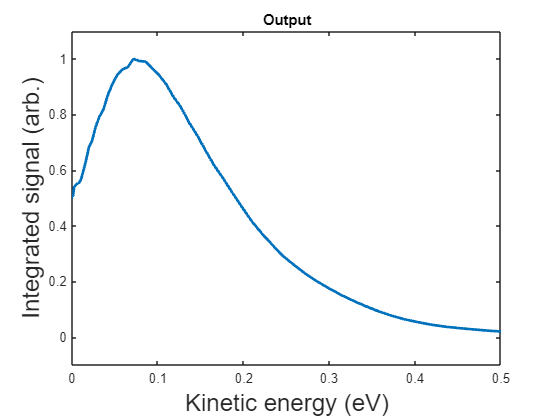


figure()
plot(energy, v_output_energy, "LineWidth", 2)
xlim([0, 0.5])
ylim([-0.1, 1.1])
xlabel("Kinetic energy (eV)", "FontSize", 18)
ylabel("Integrated signal (arb.)", "FontSize", 18)
title("Output")

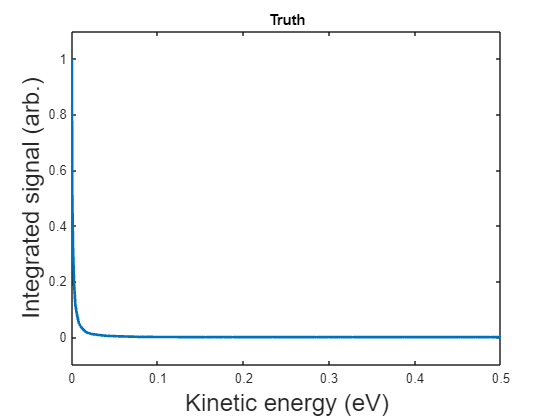


figure()
plot(energy, v_truth_energy, "LineWidth", 2)
xlim([0, 0.5])
ylim([-0.1, 1.1])
xlabel("Kinetic energy (eV)", "FontSize", 18)
ylabel("Integrated signal (arb.)", "FontSize", 18)
title("Truth")

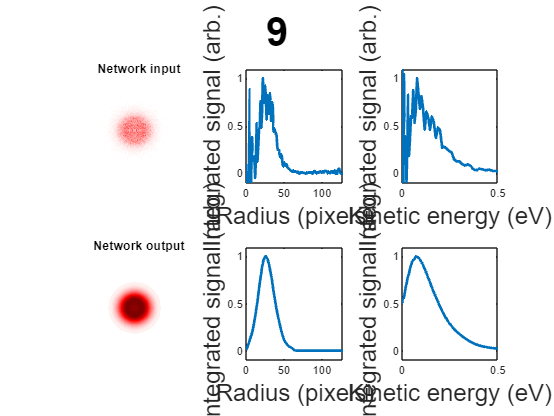





energy_max = 0.5;

% subplot(331)
subplot(231)
showim_subplot(noisy_fs, 1)
title("Network input")
shading flat

% subplot(332)
subplot(232)
[v_input, r] = velocity_dist(noisy_fs, 180);
plot(r, v_input, "LineWidth", 2)
xlim([0, max(r)])
ylim([-0.1, 1.1])
xlabel("Radius (pixels)", "FontSize", 18)
ylabel("Integrated signal (arb.)", "FontSize", 18)
% title("Input")

% subplot(333)
subplot(233)
plot(energy, v_input_energy, "LineWidth", 2)
xlim([0, energy_max])
ylim([-0.1, 1.1])
xlabel("Kinetic energy (eV)", "FontSize", 18)
ylabel("Integrated signal (arb.)", "FontSize", 18)
% title("Input")


% subplot(334)
subplot(234)
network_output_fs = flipcat_4fold_bl(network_output(:, :, N));
showim_subplot(network_output_fs, 1)
title("Network output")
shading flat

% subplot(335)
subplot(235)
[v_output, r] = velocity_dist(network_output_fs, 180);
plot(r, v_output, "LineWidth", 2)
xlim([0, max(r)])
ylim([-0.1, 1.1])
xlabel("Radius (pixels)", "FontSize", 18)
ylabel("Integrated signal (arb.)", "FontSize", 18)
% title("Output")

% subplot(336)
subplot(236)
plot(energy, v_output_energy, "LineWidth", 2)
xlim([0, energy_max])
ylim([-0.1, 1.1])
xlabel("Kinetic energy (eV)", "FontSize", 18)
ylabel("Integrated signal (arb.)", "FontSize", 18)
% title("Output")


% subplot(337)
% showim_subplot(noisefree_fs, 1)
% title("Truth")
% shading flat

% subplot(338)
% plot(r, v_truth, "LineWidth", 2)
% xlim([0, max(r)])
% ylim([-0.1, 1.1])
% xlabel("Radius (pixels)", "FontSize", 18)
% ylabel("Integrated signal (arb.)", "FontSize", 18)
% % title("Output")

% subplot(339)
% plot(energy, v_truth_energy, "LineWidth", 2)
% xlim([0, 1.0])
% ylim([-0.1, 1.1])
% xlabel("Kinetic energy (eV)", "FontSize", 18)
% ylabel("Integrated signal (arb.)", "FontSize", 18)
% % title("Output")


% sgtitle(frames(N) + " Frames", "FontWeight", "bold", "FontSize", 30)
sgtitle(N, "FontWeight", "bold", "FontSize", 30)

## Create waterfall plot

newsection("Create waterfall plot");

---------------------------------------------------------------------------
Create waterfall plot
---------------------------------------------------------------------------


if ch1 == real_or_art(1)

    for N = 1:9

        network_output_fs(:, :, N) = flipcat_4fold_bl(network_output(:, :, N));
        % showim(network_output_fs, 1)
        % title("Network output")
        % shading flat

        [v_output(:, :, N), r] = velocity_dist(network_output_fs(:, :, N), 180);

        % v_output(:, :, 1) = v_truth;

        v_output_sq = squeeze(v_output);

        network_input_fs(:, :, N) = flipcat_4fold_bl(network_input(:, :, N));
        % showim(network_output_fs, 1)
        % title("Network output")
        % shading flat

        [v_input(:, :, N), r] = velocity_dist(network_input_fs(:, :, N), 180);

        v_input_sq = squeeze(v_input);

    end

    v_truth_big = zeros(128, 50);
    v_truth_big(:, 1) = v_truth;

    v_output_sq_exp = NaN(size(v_output_sq, 1), size(v_output_sq, 2) + 1);
    v_output_sq_exp(:, 2:end) = v_output_sq;

    figure()
    p = waterfall(r(1:75), 1:10, v_output_sq_exp(1:75, :)');
    p.EdgeColor = "#0072BD";
    p.LineWidth = 1.5;
    p.FaceAlpha = 0.1;

    hold on

    p = waterfall(r(1:75), 1, v_truth_big(1:75, 1)');
    p.EdgeColor = "#000000";
    p.LineWidth = 1.5;
    p.FaceAlpha = 0.5;

    hold off

    xlim([0, 75])
    xlabel("Radius (pixels)", "FontSize", 18)
    zlim([-0.1, 1.1])
    zlabel("Integrated signal (arb.)", "FontSize", 18)

    figure()
    p = waterfall(r(1:75), 2:1:9, v_input_sq(1:75, 2:1:9)');
    p.EdgeColor = "#0072BD";
    p.LineWidth = 1.5;

    xlim([0, 75])
    xlabel("Radius (pixels)", "FontSize", 18)
    zlim([-0.1, 1.1])
    zlabel("Integrated signal (arb.)", "FontSize", 18)



elseif ch1 == real_or_art(2)

    for N = 1:50

        network_output_fs(:, :, N) = flipcat_4fold_bl(network_output(:, :, N));
        % showim(network_output_fs, 1)
        % title("Network output")
        % shading flat

        [v_output(:, :, N), r] = velocity_dist(network_output_fs(:, :, N), 180);

        % v_output(:, :, 1) = v_truth;

        v_output_sq = squeeze(v_output);

        network_input_fs(:, :, N) = flipcat_4fold_bl(network_input(:, :, N));
        % showim(network_output_fs, 1)
        % title("Network output")
        % shading flat

        [v_input(:, :, N), r] = velocity_dist(network_input_fs(:, :, N), 180);

        v_input_sq = squeeze(v_input);

        v_truth_big = zeros(128, 50);
        v_truth_big(:, 1) = v_truth;
        v_output_sq_exp = NaN(size(v_output_sq, 1), size(v_output_sq, 2) + 1);
        v_output_sq_exp(:, 2:end) = v_output_sq;

    end

    figure()
    p = waterfall(r(1:75), 2:2:50, v_output_sq_exp(1:75, 2:2:50)');
    p.EdgeColor = "#0072BD";
    p.LineWidth = 1.5;
    p.FaceAlpha = 0.1;

    hold on

    p = waterfall(r(1:75), 1, v_truth_big(1:75, 1)');
    p.EdgeColor = "#000000";
    p.LineWidth = 1.5;
    p.FaceAlpha = 0.5;

    hold off

    xlim([0, 75])
    xlabel("Radius (pixels)", "FontSize", 18)
    zlim([-0.1, 1.1])
    zlabel("Integrated signal (arb.)", "FontSize", 18)

    figure()
    p = waterfall(r(1:75), 2:2:50, v_input_sq(1:75, 2:2:50)');
    p.EdgeColor = "#0072BD";
    p.LineWidth = 1.5;

    xlim([0, 75])
    xlabel("Radius (pixels)", "FontSize", 18)
    zlim([-0.1, 1.1])
    zlabel("Integrated signal (arb.)", "FontSize", 18)


end

Index in position 3 exceeds array bounds. Index must not exceed 9.

## Data from Alex - individual slices of different stats levels

newsection("Data from Alex - individual slices of different stats levels");

View data

res = 180;

j = 9;
frames = ["2000", "4000", "6000", "8000", "10000", "15000", "20000", "50000", "100000"];
filename = "20181206_combined_bg_subtracted_mass_CF2I+.dat";

% image_sliced = table2array(readtable("C:\Users\nlhdr\OneDrive - Heriot-Watt University\PhD\Projects\Denoising for Oxford\Data_slicing_CF3I\" + frames(j) + "_frames\" + filename + ""));
% image(:, :, i) = table2array(readtable("C:\Users\nlhdr\OneDrive - Heriot-Watt University\PhD\Projects\Denoising for Oxford\Centred Data from Alex (10.01.24)\" + filename(i) + ""));
% showim(image_sliced, 1) 
% shading flat


% targetSize = [res res];
% box = centerCropWindow2d(size(image_sliced), targetSize);
% 
% image_sliced_cropped = imcrop(image_sliced, box);
% showim(image_sliced_cropped, 1)
% shading flat
% 
% image_sliced_cropped_noneg = max(image_sliced_cropped, 0);
% showim(image_sliced_cropped_noneg, 1)
% shading flat


Ready all slices of a specific fragment for network processing

% clear process_quadrant;
% 
% for j = 1:9
%     frames = ["2000", "4000", "6000", "8000", "10000", "15000", "20000", "50000", "100000"];
%     % filename = "20181206_combined_bg_subtracted_mass_CF2I+_centred.dat";
%     % filename = "20181206_combined_bg_subtracted_mass_CF3+_centred.dat";  
%     % filename = "20181206_combined_bg_subtracted_mass_I+_centred.dat";
% 
%     image_sliced = table2array(readtable("C:\Users\nlhdr\OneDrive - Heriot-Watt University\PhD\Projects\Denoising for Oxford\Data_slicing_CF3I\" + frames(j) + "_frames\" + filename + ""));
%     targetSize = [180 180];
%     box = centerCropWindow2d(size(image_sliced), targetSize);
% 
%     image_sliced_cropped = imcrop(image_sliced, box);
%     image_sliced_cropped_noneg = max(image_sliced_cropped, 0);
% 
%     image_sliced_cropped_noneg = rescale(image_sliced_cropped_noneg);
% 
%     image_quadrant = image_sliced_cropped_noneg;
% 
%     image_quadrant_bottomleft =  image_quadrant(1:(res/2), 1:(res/2));
%     image_quadrant_topright =  image_quadrant((res/2+1):end, (res/2+1):end);
%     image_quadrant_bottomright = image_quadrant(1:(res/2), (res/2+1):end);
%     % image_quadrant_bottomright = zeros(90, 90);
%     image_quadrant_topleft = image_quadrant((res/2+1):end, 1:(res/2));
% 
%     % bottomleft
% 
%     input = image_quadrant_bottomleft;
%     flipped_v = flip(input, 2);
%     added = cat(2, input, flipped_v);
% 
%     flipped = flip(added, 1);
% 
%     added = cat(1, added, flipped);
% 
%     image_centred_using_quadrant_bottomleft = added;
% 
%     % topright
% 
%     input = image_quadrant_topright;
%     flipped_v = flip(input, 2);
%     added = cat(2, flipped_v, input);
% 
%     flipped = flip(added, 1);
%     added = cat(1, flipped, added);
%     image_centred_using_quadrant_topright = added;
% 
%     % bottomright
% 
%     input = image_quadrant_bottomright;
%     flipped_v = flip(input, 2);
%     added = cat(2, flipped_v, input);
% 
%     flipped = flip(added, 1);
%     added = cat(1, added, flipped);
%     image_centred_using_quadrant_bottomright = added;
% 
%     % topleft
% 
%     input = image_quadrant_topleft;
%     flipped_v = flip(input, 1);
%     added = cat(1, flipped_v, input);
% 
%     flipped = flip(added, 2);
%     added = cat(2, added, flipped);
% 
%     image_centred_using_quadrant_topleft = added;
% 
% 
%     image_symmetrised = image_centred_using_quadrant_bottomleft + image_centred_using_quadrant_topright + image_centred_using_quadrant_bottomright + image_centred_using_quadrant_topleft;
% 
%     image_symmetrised = rescale(image_symmetrised);
% 
%     % process_quadrant(:, :, j) = image_sliced_cropped_noneg(1:(res/2), 1:(res/2), :);
%     process_quadrant(:, :, j) = image_symmetrised(1:(res/2), 1:(res/2), :);
% 
%     showim(process_quadrant(:, :, j), 1)
%     shading flat
%     title(frames(j) + " Frames - Quadrant")
%     %
%     % showim(image_sliced_cropped_noneg, 1)
%     % shading flat
%     % title(frames(j) + " Frames")
%     % 
%     showim(image_symmetrised, 1)
%     shading flat
%     title(frames(j) + " Frames")
% end

% save("noisy_process_real", "process_quadrant")
